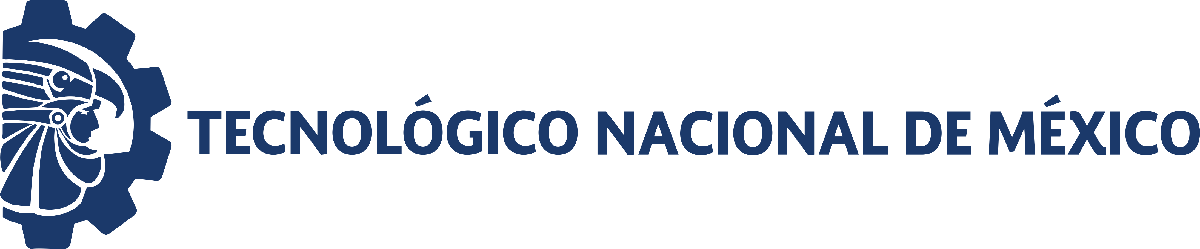                                 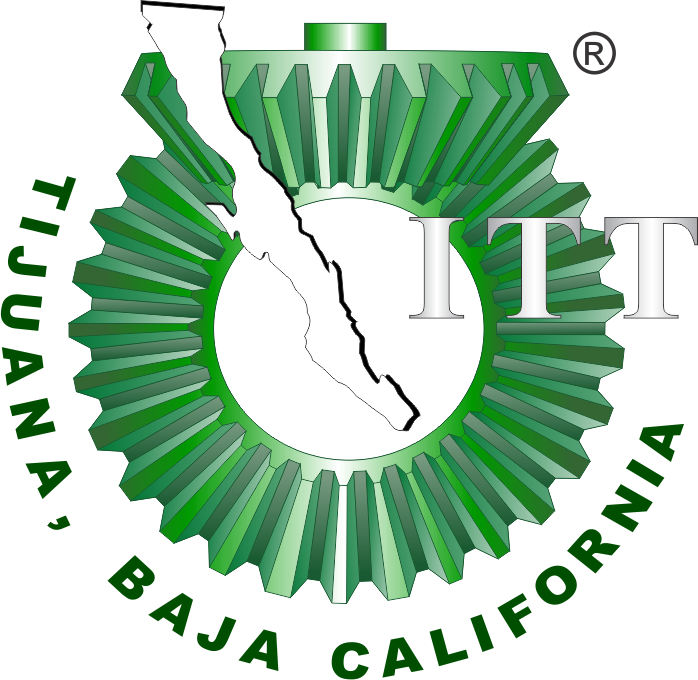

# Práctica uno: Diseño de controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

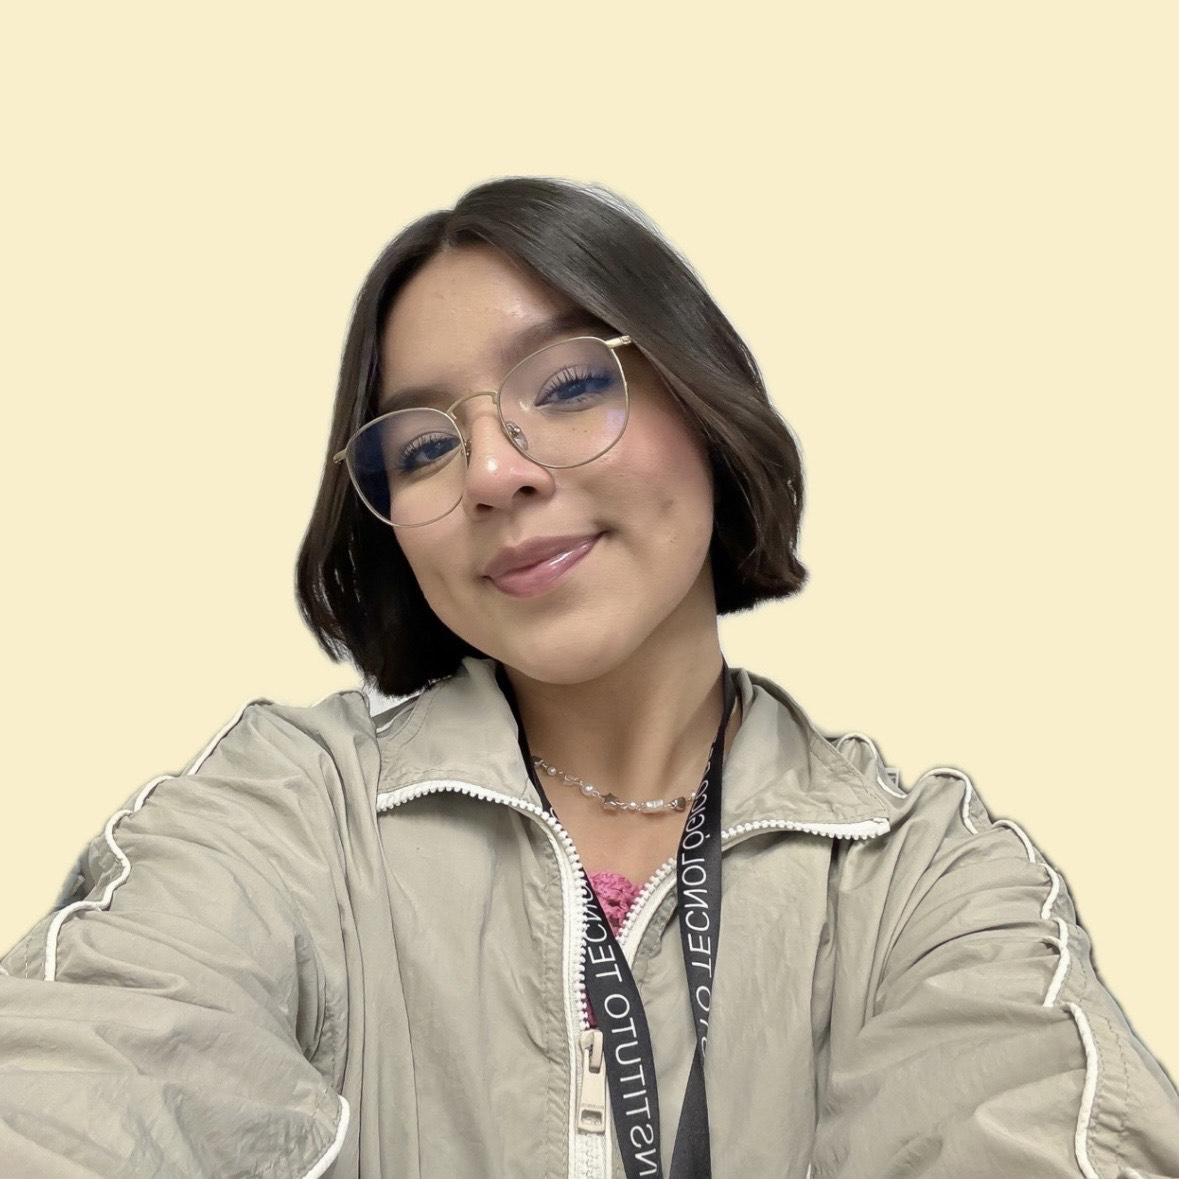

Nombre del alumno: **Leslie Avelladith Marin Paredes **

Número de control: **20212506**

Correo institucional: **l20212506@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10'; 
file = 'sys2';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'PI';

## Respuesta al escalón

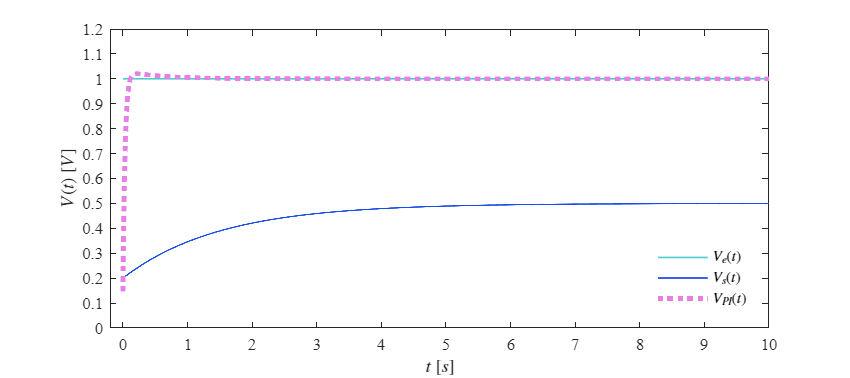

Signal = 'Escalon';
set_param('sys2/S1','sw','1');
set_param('sys2/Ve(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.VPID,Signal) %to workspace buscar en el library browser del sysp0 

## Respuesta al impulso

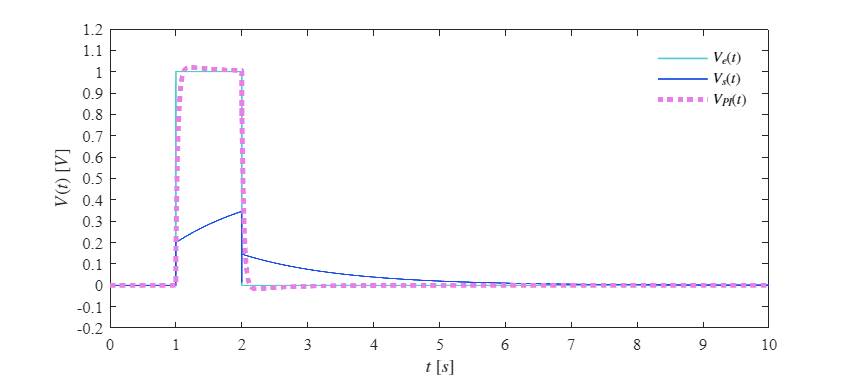

Signal = 'Impulso';
set_param('sys2/S1','sw','0');
set_param('sys2/Ve(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.VPID,Signal) %to workspace buscar en el library browser del sysp0 

## Respuesta a la rampa

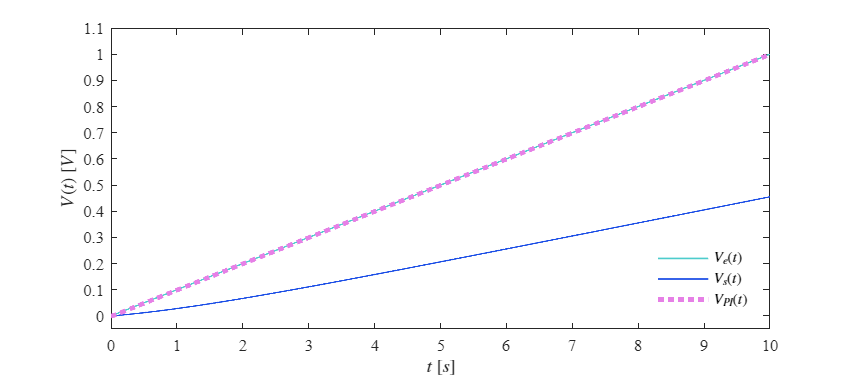

Signal = 'Rampa';
set_param('sys2/S2','sw','1');
set_param('sys2/Ve(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.VPID,Signal) %to workspace buscar en el library browser del sysp0 

## Respuesta a la función sinusoidal

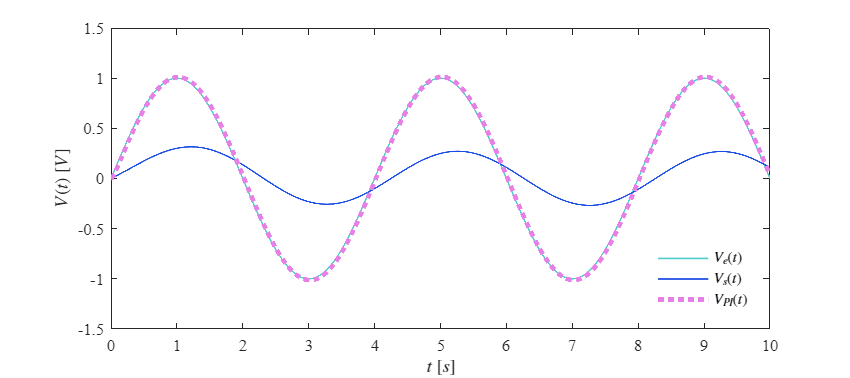

Signal = 'Ramp';
set_param('sys2/S2','sw','0');
set_param('sys2/Ve(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.VPID,Signal) %to workspace buscar en el library browser del sysp0 

## **Función: Respuesta a las señales**

function plotsignals(t,Ve,Vs,VPID,Signal)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10, 'points')
    am = [0.3,0.8,0.8];
    rf = [0.1,0.3,0.9];
    na = [0.9,0.5,0.9];
    hold on; grid off; box on

    plot(t,Ve,'LineWidth',1,'Color',am)
    plot(t,Vs,'LineWidth',1,'Color',rf)
    plot(t,VPID,':','LineWidth',3,'Color',na)

    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$V(t)$ $[V]$','Interpreter','Latex')

    L = legend('$V_e(t)$','$V_s(t)$','$V_{PI}(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    if Signal == "Escalon"
        xlim([-0.2,10]); xticks(0:1:10)  %dominio
        ylim([0,1.2]); yticks(0:0.1:1.2)  %rango
    elseif Signal == "Impulso"
        xlim([0,10]); xticks(0:1:10)
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)
    elseif Signal == "Rampa"
        xlim([0,10]); xticks(0:1:10)
        ylim([-0.05,1.1]); yticks(0:0.1:1.1)
    elseif Signal == "Sinusoidal"
        xlim([0,10]); xticks(0:1:10)
        ylim([-1.2,1.2]); yticks(-1.2:0.2:1.2)
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end